This script analyze running vs resting data from mouse 1610.

cd('/Volumes/PcSSDA/RvR/20220325_1610_RvR_001')
ExperimentName='20220325_1610_RvR_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),'_20220403.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end


This part is to write the csv files.


    filename=[analysis_name,num2str(i),'_20220403.mat'];
    load(filename)
    
    time_csv=[analysis_name,num2str(i),'_time.csv'];
    intensity_csv=[analysis_name,num2str(i),'_intensity.csv'];
    lft_fit_csv=[analysis_name,num2str(i),'_tau_fitting.csv'];
    lft_emp_csv=[analysis_name,num2str(i),'_tau_emp.csv'];
    
    csvwrite(time_csv,time);
    csvwrite(intensity_csv,photoncount);
    csvwrite(lft_fit_csv,tau_avg);
    csvwrite(lft_emp_csv,tau_empTrunc);


cd('/Volumes/PcSSDA/RvR/20220325_1610_RvR_001')
load('20220325_1610_RvR_001_analysis_1_20220403.mat')

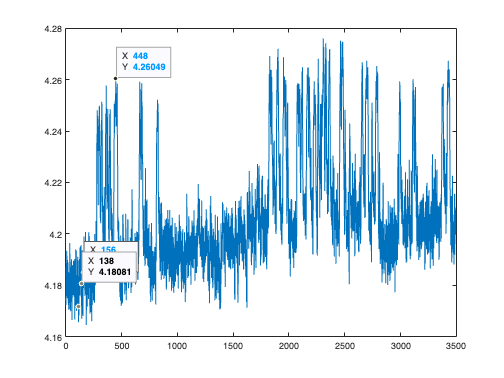

figure
plot(tau_empTrunc)

resting_index=156;
running_index=448;
lft_hist_1610_resting=lifetime_histograms(:,resting_index);
lft_hist_1610_resting=lifetime_histograms(:,running_index);

colnames={'time','intensity','tau_empirical','tau_fit'}

colnames = 1×4 cell array
    {'time'}    {'intensity'}    {'tau_empirical'}    {'tau_fit'}


FLP_all=table(time, photoncount, tau_empTrunc, tau_avg, 'VariableNames',colnames)
FLP_all_csv=[analysis_name,'_FLP_allData.csv']

FLP_all_csv = '20220325_1610_RvR_001_analysis__FLP_allData.csv'

writetable(FLP_all, FLP_all_csv)

Running vs resting number 2

cd('/Volumes/PcSSDA/RvR/20220330_1610_RvR_002')

Error using cd
Unable to change current folder to '/Volumes/PcSSDA/RvR/20220330_1610_RvR_002' (Name is nonexistent or not a folder).

ExperimentName='20220330_1610_RvR_002'; % Give a specific name to this experiment or this analysis
FirstAcq=8;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),'_20220403.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end


This part is to write the csv files.


    filename=[analysis_name,num2str(i),'_20220403.mat'];
    load(filename)
    
    time_csv=[analysis_name,num2str(i),'_time.csv'];
    intensity_csv=[analysis_name,num2str(i),'_intensity.csv'];
    lft_fit_csv=[analysis_name,num2str(i),'_tau_fitting.csv'];
    lft_emp_csv=[analysis_name,num2str(i),'_tau_emp.csv'];
    
    csvwrite(time_csv,time);
    csvwrite(intensity_csv,photoncount);
    csvwrite(lft_fit_csv,tau_avg);
    csvwrite(lft_emp_csv,tau_empTrunc);
    
    

Running vs resting number 3

cd('/Volumes/PcSSDA/RvR/20220330_1610_RvR_003')
ExperimentName='20220330_1610_RvR_003'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

for i=1:number_of_acq
    
    load([FLPfiles num2str(i+FirstAcq-1) '.mat']);
    filename=[analysis_name,num2str(i),'_20220403.mat'];
    FLiPAnalysis_Tau_p1_Photon(FLPdata_time, FLPdata_lifetimes, timebin,ch, filename)
    load(filename);
    
    time(isnan(time))=[];
    photoncount(isnan(photoncount))=[];
    tau_avg(isnan(tau_avg))=[];
    tau_avgTrunc(isnan(tau_avgTrunc))=[];
    tau_empTrunc(isnan(tau_empTrunc))=[];
    p1(isnan(p1))=[];
    chi2(isnan(chi2))=[];

    save(filename, 'time','photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1','chi2','beta2','beta4','beta5','beta6','lifetime_histograms');

    
end


This part is to write the csv files.


    filename=[analysis_name,num2str(i),'_20220403.mat'];
    load(filename)
    
    time_csv=[analysis_name,num2str(i),'_time.csv'];
    intensity_csv=[analysis_name,num2str(i),'_intensity.csv'];
    lft_fit_csv=[analysis_name,num2str(i),'_tau_fitting.csv'];
    lft_emp_csv=[analysis_name,num2str(i),'_tau_emp.csv'];
    
    csvwrite(time_csv,time);
    csvwrite(intensity_csv,photoncount);
    csvwrite(lft_fit_csv,tau_avg);
    csvwrite(lft_emp_csv,tau_empTrunc);

i=1;
filename=[analysis_name,num2str(i),'_20220403.mat'];
load(filename)

colnames={'time','intensity','tau_empirical','tau_fit'}

colnames = 1×4 cell array
    {'time'}    {'intensity'}    {'tau_empirical'}    {'tau_fit'}


FLP_all=table(time, photoncount, tau_empTrunc, tau_avg, 'VariableNames',colnames)

FLP_all_csv=[analysis_name,'_FLP_allData.csv']

FLP_all_csv = '20220330_1610_RvR_003_analysis__FLP_allData.csv'

writetable(FLP_all, FLP_all_csv)